# Finite Element Formulation of the linear Timoshenko beam

## Introduction

The problem at hand is a straight beam for which shear deformations are allowed and which is subject to external forces (and possibly also moments), see the following figure:

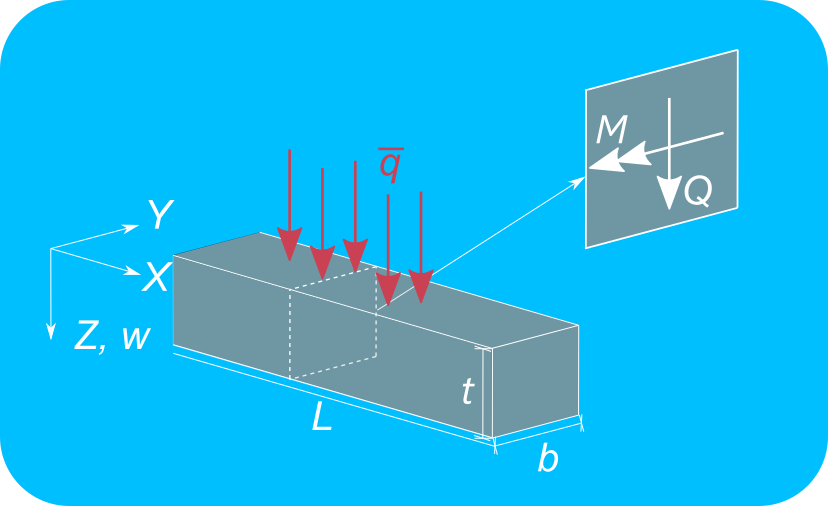

The governing equations for the aforementioned problem are provided in Eq. set (1), namely,


$$\begin{array}{l}
\bar{q} +\frac{\textrm{dQ}}{\textrm{dx}}=0\;\textrm{for}\;x\in \left\lbrack 0,l\right\rbrack ,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\ldotp 1\right)\\
\bar{m} +\frac{\textrm{dM}}{\textrm{dx}}-Q=0\;\textrm{for}\;x\in \left\lbrack 0,l\right\rbrack \ldotp \;\;\;\;\;\;\;\;\;\;\left(1\ldotp 2\right)
\end{array}$$


where $Q,M$are the reaction shear forces and moments, respectively, and where $\bar{q}, \bar{m}$ are the externally applied lateral forces and moments, respectively. The beam can only deform vertically $w(x)$ and have its cross section rotated at each Cartesian location $\beta(x)$. The problem at hand is reduced to one dimension by integrating the resultant forces along the beam's cross section. The material law (constitutive law) that relates the resultant forces and moments with the strains is given by the following equations:


$$\begin{array}{l}
Q\left(\gamma \right)=\alpha \textrm{GA}\gamma ,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\ldotp 1\right)\\
M\left(\kappa \right)=\textrm{EI}\kappa \ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\ldotp 2\right)
\end{array}$$


The shear deformation is the sum of the total cross sectional rotation $\beta(x)$ and the rotation due to as a result of the vertical deformation change $\text{d} w / \text{d} x$, whereas the change in curvature $\kappa(x)$ is the change of the total cross-sectional rotation along the x-Cartesian coordinate. These are the so-called kinematic equations and are summarized below:


$$\begin{array}{l}
\gamma =\frac{\textrm{dw}}{\textrm{dx}}+\beta ,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(3\ldotp 1\right)\\
\kappa =\frac{d\beta }{\textrm{dx}}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(3\ldotp 2\right)
\end{array}$$


To derive the to the weak form of the problem from the strong form, one needs to multiply equations (1.1) and (1.2) with arbitrary variations $\delta w$ and $\delta \beta$, respectively, both of which fulfil the corresponding boundary conditions and to subsequently perform integration by parts in order to reduce the variational index of the problem and be able to apply Dirichlet and Neumann boundary conditions, namely,


$$\begin{array}{l}
\int_0^l \left(\frac{\textrm{dQ}}{\textrm{dX}}+\bar{q} \right)\delta w\;\textrm{dx}=0\Rightarrow \\
-\int_0^l Q\;\delta \frac{\textrm{dw}}{\textrm{dx}}\;\textrm{dx}+Q\left(X_L \right)\delta W\left(X_L \right)-Q\left(X_0 \right)\delta W\left(X_0 \right)+\int_0^l \bar{q} \;\delta w\;\textrm{dx}=0,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(4\ldotp 1\right)\\
\int_0^l \left(\frac{\textrm{dM}}{\textrm{dx}}-Q+\bar{m} \right)\delta \beta \;\textrm{dx}=0\Rightarrow \\
-\int_0^l M\;\delta \frac{d\beta }{\textrm{dx}}\;\textrm{dx}-\int_0^l Q\;\delta \beta \;\textrm{dx}+M\left(X_L \right)\;\delta \beta \left(X_L \right)-M\left(X_0 \right)\;\delta \beta \left(X_0 \right)+\int_0^l \bar{m} \;\delta \beta \;\textrm{dx}=0\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\left(4\ldotp 2\right)
\end{array}$$


Finally Eqs. (5.1) and (5.2) are added in order to obtain the final form of the total weak formulation of the Timoshenko problem, namely,


$$\overbrace{ - \int_{0}^{l} Q \left(  \frac{\text{d} \, \delta w}{\text{d} x} + \delta \beta \right) \, \text{d}x - \int_{0}^{l} M \frac{\text{d} \, \delta \beta}{\text{d} x} \, \text{d} x}^{\delta W_{\text{int}}} + \overbrace{ \int_{0}^{l} \bar{q} \, \delta w \, \text{d} x + \int_{0}^{l} \bar{m} \, \delta \beta \, \text{d} x }^{\delta W_{\text{ext}}} + \overbrace{ Q_0 \, \delta w_0 + Q_l \, \delta w_l + M_l \, \delta \beta_l + M_l \, \delta \beta_l }^{\text{boundary terms}} = 0     \quad (5)$$


where$Q_0 =-Q\left(X_0 \right)$ and $M_0 =-M\left(X_0 \right)$.

The example problem is herein a cantiliver beam subject to uniform vertical load, see the following figure,

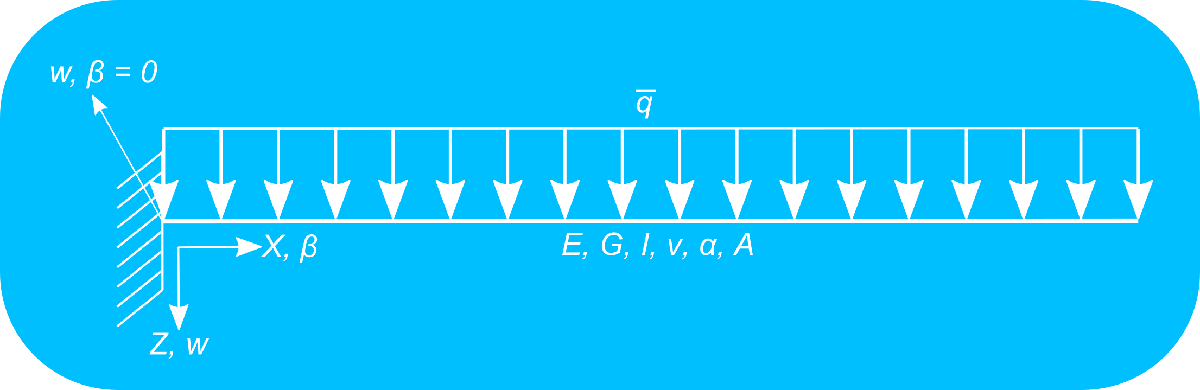

For this problem there is an analytical solution in terms of the vertical deflection field given by the following relationship:


$$w(X) = \frac{1}{\alpha G A} \left( \overline{q} L X - \frac{\overline{q} X^2}{2} \right) - \frac{1}{EI} \left( - \frac{\overline{q} X^4}{24} + \frac{\overline{q} L X^3}{6} - \frac{\overline{q} L^2 X^2}{4} \right) \qquad (6)$$


which is a fourth-order polynomial in space. To obtain the reference solution in terms of the cross-sectional rotation we can insert Eq. (3.1) into Eq.(2.1), then substitute the resultant transverse shear force $Q$ into Eq. (1.1), substitute the solution provided in Eq. (6) in the resulting expression and finally integrate over the computational domain $\left\lbrack 0,L\right\rbrack$ to obtain an analytical expression for the cross-sectional rotation, namely,


$$\beta(X) = \int_0^L - \frac{1}{\alpha G A} \overline{q} - \frac{\text{d}^2 w}{\text{d} x^2} \; \text{d} X \qquad (7)$$


For the integration presented in Eq. (7) it is leveraged the homogeneous Dirichlet boundary conditions which results in a zero integration constant. It is shown in this code section how the [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html)™ in [MATLAB](https://www.mathworks.com/products/matlab.html)® can be used to obtain an analytical expression for equation (7) in only one line of code.

We can then compare the solution obtained by the Finite Element discretizations against these analytical solutions.

[PREVIOUS Chapter](matlab:open('..\1_BasisFunctions\main_Chapter1_BasisFunctions.mlx')) *Basis Functions*

[NEXT Chapter](matlab:open('..\3_ReissnerMindlinPlate\main_Chapter3_AShearDeformablePlateElement.mlx')) *Finite Element Formulation of the linear Reissner-Mindlin Plate*

**Author: Andreas Apostolatos, PhD (aapostol@mathworks.com)**

**Date: 20.02.2023**

## Preamble

clc;
clear;
close all;

## **Problem setup**

### Definition of the geometric parameters

Thickness [m]

propStr.t = 10^(0);

Width [m]

propStr.b = .1;

Height [m]

propStr.A = propStr.b*propStr.t;

X-coordinate at the left end of the beam [m]

X0 = 0;

Y-coordinate at the right end of the beam [m]

XL = 4;

### Definition of the loading and material paramerters

Distributed load along the beam's length [N/m]

propStr.qBar = -3e4*(propStr.t)^3;

Distributed moment along the beam's length [N]

propStr.mBar = 0;

Young's modulus [N/m^2]

propStr.E = 1e7;

Poisson ratio [dimensionless]

propStr.nu = .3;

Moment of inertia [m^4]

propStr.I = propStr.b*(propStr.t^3)/12;

Shear modulus (connected to epsilon_12 = E/(1+nu)) [N/m^2]

propStr.G = propStr.E/(2*(1 + propStr.nu));

Shear correction factor [dimensionless]

propStr.alpha = 5/6;

## Derivation of the analytical solution

Since the plate is rectangular, clamped on its one end while being subject to constant distributed vertical load its behavior is expected to resemble a beam aligned with the $X$-axis, whereas no effects are expected to take place along the $Y$-axis. The analytical solution for this problem using the shear-deformable Timoshenko beam formulation are in this case as follows

syms wEx(X) betaEx(X) Lsym qsym Gsym Aqsym Esym Isym

Set the analytical solution in terms of the vertical deflection field (Eq. (6) in the introduction):

$w(X) = \frac{1}{\alpha G A} \left( \overline{q} L X - \frac{\overline{q} X^2}{2} \right) - \frac{1}{EI} \left( - \frac{\overline{q} X^4}{24} + \frac{\overline{q} L X^3}{6} - \frac{\overline{q} L^2 X^2}{4} \right) \qquad (8)$,

namely:

wEx(X) = (qsym*Lsym*X-qsym*X^2/2)/Gsym/(Aqsym) - ...
    (-qsym*X^4/24+qsym*Lsym*X^3/6-qsym*Lsym^2*X^2/4)/Esym/Isym;

Get the analytical solution of the rotational field by leveraging the Partial Differential Equation (PDE) of the problem and the functions of the [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html)™ in [MATLAB](https://www.mathworks.com/products/matlab.html)®


$$\beta(X) = \int_{0}^L - \frac{1}{\alpha G A}\overline{q} - \frac{\text{d}^2 w}{\text{d} x^2} \: \text{d}x \qquad (9)$$


betaEx(X) = int(-1/(propStr.alpha*propStr.G*propStr.b*propStr.t)*propStr.qBar ...
    - diff(diff(wEx, X), X));

Evaluate the expressions for the given geometric and material parameters

wEx(X) = subs(wEx,{Lsym, qsym, Gsym, Esym, Isym, Aqsym}, ...
    {XL, propStr.qBar, propStr.G, propStr.E, propStr.b*(propStr.t^3)/12, ...
    propStr.alpha*propStr.b*propStr.t});
betaEx(X) = subs(betaEx,{Lsym, qsym, Gsym, Esym, Isym, Aqsym}, ...
    {XL, propStr.qBar, propStr.G, propStr.E, propStr.b*(propStr.t^3)/12, ...
    propStr.alpha*propStr.b*propStr.t});

## **Basis functions**

### Linear shape functions


$$\begin{array}{l}
N_1 \left(\xi \right)=\frac{1-\xi }{2},\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(10\ldotp 1\right)\\
N_2 \left(\xi \right)=\frac{1+\xi }{2}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(10\ldotp 2\right)
\end{array}$$


#### Definition of the one-dimensional linear Lagrange polynomials

syms l1L1(X, X1, X2) l2L1(X, X1, X2)
l1L1(X, X1, X2) = (X - X2)/(X1 - X2);
l2L1(X, X1, X2) = (X - X1)/(X2 - X1);

#### Definition and visualization of the one-dimensional linear (hat) basis functions

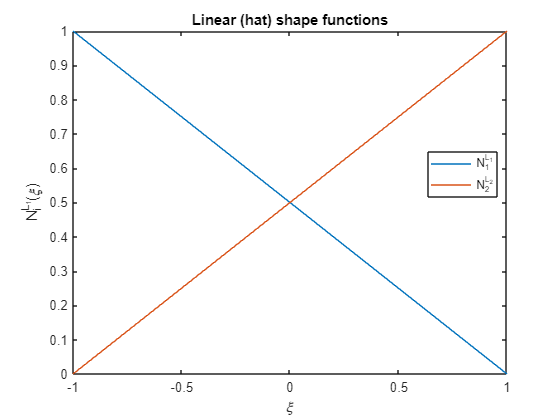

syms xi N1L1(xi) N2L1(xi) NL1(xi)
N1L1(xi) = l1L1(xi, -1, +1);
N2L1(xi) = l2L1(xi, -1, +1);
NL1(xi) = [N1L1(xi) N2L1(xi)];
fplot(NL1, [-1 1]);
xlabel("\xi");
ylabel("N_i^{L_1}(\xi)")
legend("N_1^{L_1}", "N_2^{L_2}", Location="best");
title("Linear (hat) shape functions")

### Quadratic shape functions


$$\begin{array}{l}
N_1 \left(\xi \right)=\frac{\xi \;\left(\xi -1\right)}{2},\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(11\ldotp 1\right)\\
N_2 \left(\xi \right)=\frac{\xi \;\left(\xi +1\right)}{2}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(11\ldotp 2\right)\\
N_3 \left(\xi \right)=-\left(\xi -1\right)\;\;\left(\xi +1\right),\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(11\ldotp 3\right)
\end{array}$$


#### Definition of the one-dimensional linear Lagrange polynomials

syms l1L2(X, X1, X2, X3) l2L2(X, X1, X2, X3) l3L2(X, X1, X2, X3)
l1L2(X, X1, X2, X3) = (X - X2)/(X1 - X2)*(X - X3)/(X1 - X3);
l2L2(X, X1, X2, X3) = (X - X1)/(X2 - X1)*(X - X3)/(X2 - X3);
l3L2(X, X1, X2, X3) = (X - X1)/(X3 - X1)*(X - X2)/(X3 - X2);

#### Definition and visualization of the one-dimensional quadratic basis functions

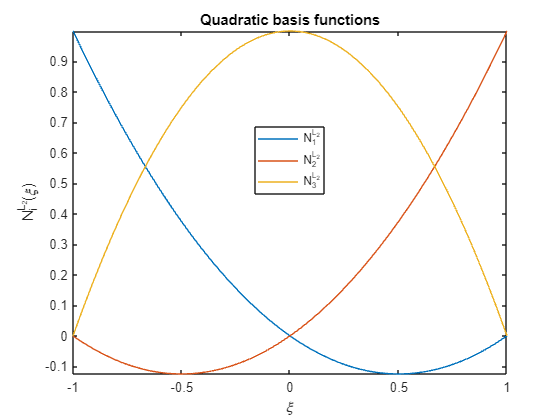

syms N1L2(xi) N2L2(xi) N3L2(xi) NL2(xi)
N1L2(xi) = l1L2(xi, -1, 0, +1);
N2L2(xi) = l2L2(xi, -1, 0, +1);
N3L2(xi) = l3L2(xi, -1, 0, +1);
NL2(xi) = [N1L2(xi) N3L2(xi) N2L2(xi)];
fplot(NL2, [-1 1]);
xlabel("\xi");
ylabel("N_i^{L_2}(\xi)")
legend("N_1^{L_2}", "N_2^{L_2}", "N_3^{L_2}", Location="best");
title("Quadratic basis functions")

## **Basis functions derivatives**

### Derivation of the parametric derivatives of the linear (hat) shape functions


$$\begin{array}{l}
\frac{{\partial N}_1 \left(\xi \right)}{\partial \xi }=-\frac{1}{2},\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(12\ldotp 1\right)\\
\frac{{\partial N}_2 \left(\xi \right)}{\partial \xi }=\frac{1}{2}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(12\ldotp 2\right)
\end{array}$$


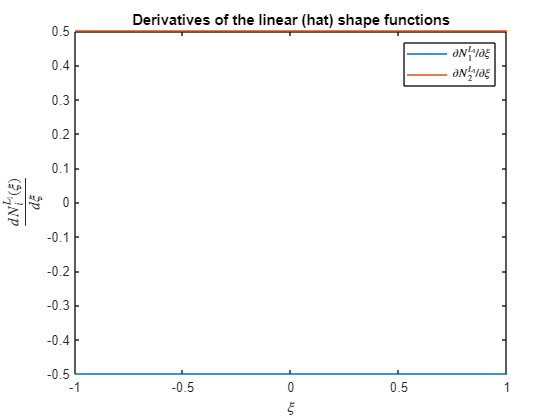

fplot(diff(NL1, xi), [-1 1]);
xlabel("\xi");
ylabel("$\frac{d N_i^{L_1}(\xi)}{d \xi}$", Interpreter="latex");
legend("$\partial N_1^{L_1} / \partial \xi$", ...
    "$\partial N_2^{L_1} / \partial \xi$", Interpreter="latex");
title("Derivatives of the linear (hat) shape functions")

### Derivation of the parametric derivatives of the quadratic basis functions


$$\begin{array}{l}
\frac{{\partial N}_1 \left(\xi \right)}{\partial \xi }=\xi -\frac{1}{2},\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(13\ldotp 1\right)\\
\frac{{\partial N}_2 \left(\xi \right)}{\partial \xi }=-2\;\xi \ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(13\ldotp 2\right)\\
\frac{{\partial N}_3 \left(\xi \right)}{\partial \xi }=\xi +\frac{1}{2}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(13\ldotp 3\right)
\end{array}$$


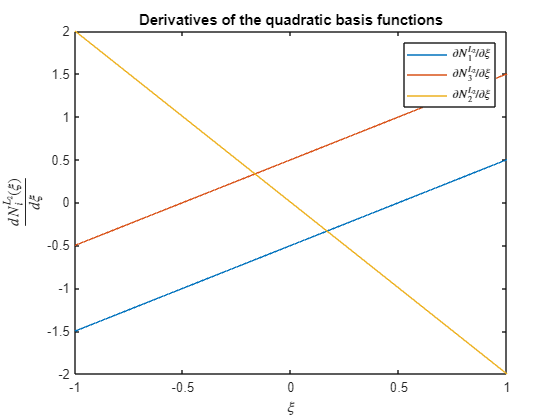

fplot(diff(NL2, xi), [-1 1]);
xlabel("\xi");
ylabel("$\frac{d N_i^{L_2}(\xi)}{d \xi}$", Interpreter="latex");
legend("$\partial N_1^{L_2} / \partial \xi$", ...
    "$\partial N_3^{L_2} / \partial \xi$", "$\partial N_2^{L_2} / \partial \xi$", ...
    Interpreter="latex");
title("Derivatives of the quadratic basis functions")

## Discretization

Both the vertical deflection $w$ and cross-sectional rotation $\beta$ fields are discretized using the same basis (shape) functions, namely:


$$\begin{array}{l}
w\left(x\right)\approx \sum_{i=1:N} N_i \;w_i ,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(14\ldotp 1\right)\\
\beta \left(x\right)\approx \sum_{i=1:N} N_i \;\beta_i \;\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(14\ldotp 2\right)
\end{array}$$


Here $N$ indicates the total number of nodes in the mesh. Moreover a Buvnov-Galerkin discretization is used, meaning that both the test and the unknown fields are discretized using the same basis (shape) functions.

### Generation and visualization of an one-dimensional mesh using linear two-noded elements

#### Mesh generation

numEl = 30;
mshL1 = generateLinearMeshOnLine(X0, XL, numEl);
isLinearMeshNonuniform = false;
if isLinearMeshNonuniform
    dX = mshL1.nodes(2, 1) - mshL1.nodes(1, 1);
    for ii = 2:numel(mshL1.nodes(:, 1)) - 1
        mshL1.nodes(ii, 1) = mshL1.nodes(ii, 1) + (2.*rand(1, 1) -1)/(4*dX);
    end
end

#### Dirichlet boundary conditions

numDOFsL1 = 2*numel(mshL1.nodes(:, 1));
freeDOFsL1 = 1:numDOFsL1;
homDOFsL1 = 1:2;
[~, idxL1] = ismember(homDOFsL1, freeDOFsL1);
freeDOFsL1(idxL1) = [];

#### Mesh plot

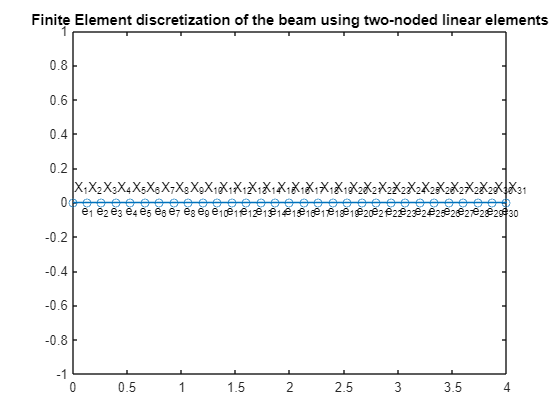

plotMesh1d(mshL1);
title("Finite Element discretization of the beam using " + ...
    "two-noded linear elements")

  **Try**

Change the flag `isLinearMeshNonuniform` to true and observe the mesh. 

 **Reflect**

What can you say about the determinant of the Jacobian for the elements that are inverted?

### Generation and visualization of an one-dimensional mesh using quadratic three-noded elements

#### Mesh generation

mshL2 = generateQuadraticMeshOnLine(mshL1);
isQuadraticMeshUniform = false;
if isQuadraticMeshUniform
    for ii = numel(mshL1.nodes(:, 1)) + 1:numel(mshL2.nodes(:, 1))
        mshL2.nodes(ii, 1) = mshL2.nodes(ii, 1) + (2.*rand(1, 1) -1)/5;
    end
end

#### Dirichlet boundary conditions

numDOFsL2 = 2*numel(mshL2.nodes(:, 1));
freeDOFsL2 = 1:numDOFsL2;
homDOFsL2 = 1:2;
[~, idxL2] = ismember(homDOFsL2, freeDOFsL2);
freeDOFsL2(idxL2) = [];

#### Mesh plot

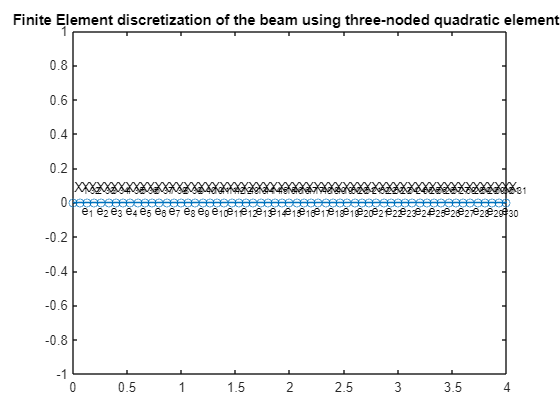

plotMesh1d(mshL2);
title("Finite Element discretization of the beam using " + ...
    "three-noded quadratic elements")

  **Try**

Change the flag `isQuadraticMeshUniform` to true and observe the mesh. 

 **Reflect**

What can you say about the distribution of the determinant of the Jacobian? For which elements do you expect it to be zero or negative?

## One-dimensional mesh along with the corresponding basis functions in the physical space

### Basis functions at given evaluation points

numPts = 100;
pts = linspace(X0, XL, numPts);
Neval = computeHatBasisFunctionValuesOnMesh(N1L1, N2L1, mshL1, numPts);

### Graph legends

legendTitle = cell(1, height(Neval));
for ii = 1:height(Neval)
    legendTitle{ii} = sprintf("$N_{%s}$", strcat(num2str(ii)));
end

### Basis functions at the evaluation points

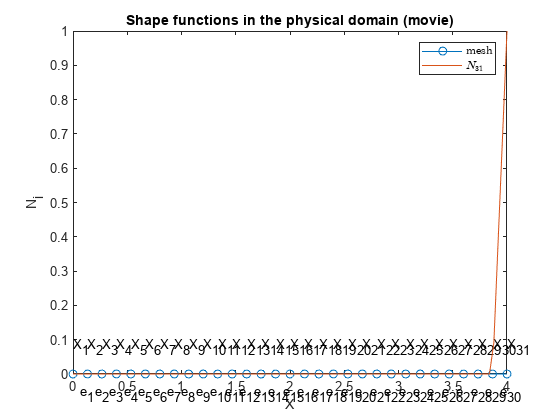

figure,
for ii = 1:numel(mshL1.nodes(:, 1))
    plotMesh1d(mshL1);
    hold on;
    plot(pts, Neval(ii, :));
    xlabel("X");
    ylabel("N_i");
    legend({"mesh", legendTitle{ii}}, "Interpreter", "latex");
    pause(2)
    hold off;
end
title("Shape functions in the physical domain (movie)")

### Basis functions at the evaluation points

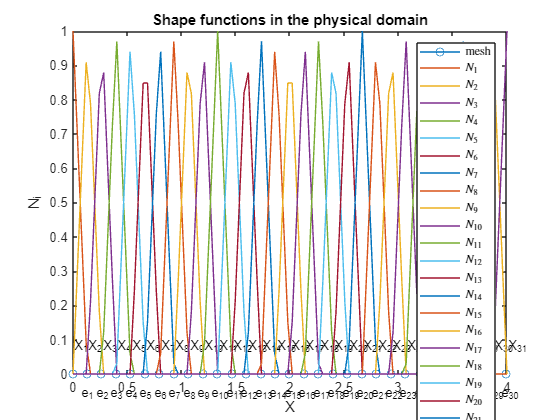

figure,
plotMesh1d(mshL1);
hold on;
plot(pts, Neval)
xlabel("X");
ylabel("N_i");
legend([{"mesh"}, legendTitle(:)'], "Interpreter", "latex");
title("Shape functions in the physical domain")
hold off;

 **Reflect**

What is the support (the area in which a function is not identically zero) of each basis function in the mesh? What is the implication of this fact in the structure of the master stiffness matrix?

## Master stiffness matrix and load vector for the two-noded linear mesh

### Initialization of the master stiffness matrix and master load vector

KL1 = zeros(numDOFsL1);
FL1 = zeros(numDOFsL1, 1);

### Loop over all the elements in the mesh and assemble to the master stiffness matrix and master load vector

for ii = 1:numEl

#### Nodal indices and nodal coordinates

    id = mshL1.elements(ii, :);
    nodesEl = mshL1.nodes(id);

#### Element stiffness matrix

    [KEl, FEl] = computeElementStiffnessMatrixandForceVectorTimoshenkoBeam ...
        (NL1, nodesEl, propStr);

#### Element Freedom Table (EFT)

    EFT = vertcat(2*id - 1, 2*id);
    EFT = EFT(:);

#### Assembly to the master stiffness matrix and load vector

    KL1(EFT, EFT) = KL1(EFT, EFT) + KEl;
    FL1(EFT) = FL1(EFT) + FEl;

end

### Sparsity of the master global stiffness matrix

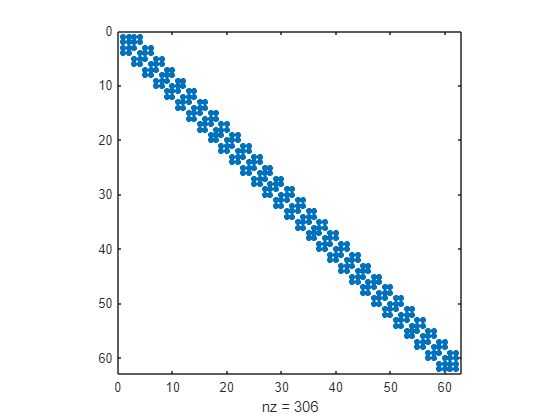

spy(KL1)

## Master stiffness matrix and load vector for the three-noded quadratic mesh

### Initialization of the master stiffness matrix and master load vector

KL2 = zeros(numDOFsL2);
FL2 = zeros(numDOFsL2, 1);

### Loop over all the elements in the mesh and assemble to the master stiffness matrix and master load vector

for ii = 1:numEl

#### Nodal indices and nodal coordinates

    id = mshL2.elements(ii, :);
    nodesEl = mshL2.nodes(id);

#### Element stiffness matrix

    [KEl, FEl] = computeElementStiffnessMatrixandForceVectorTimoshenkoBeam ...
        (NL2, nodesEl, propStr);

#### Element Freedom Table (EFT)

    EFT = vertcat(2*id - 1, 2*id);
    EFT = EFT(:);

#### Assembly to the master stiffness matrix and load vector

    KL2(EFT, EFT) = KL2(EFT, EFT) + KEl;
    FL2(EFT) = FL2(EFT) + FEl;

end

### Sparsity of the master global stiffness matrix

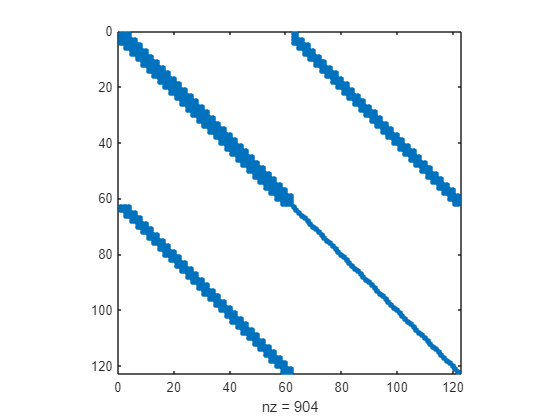

spy(KL2)

 **Reflect**

Why are there stiffness matrix entries far from the main diagonal? Does this indicate that the support of the quadratic basis functions is not confined in each element's area?

## Solution of the Timoshenko beam problem

### Two-noded linear elements

#### Solution of the linear equation system

u_L1 = zeros(numDOFsL1, 1);
u_L1(freeDOFsL1) = KL1(freeDOFsL1, freeDOFsL1)\FL1(freeDOFsL1);

#### Visualization of the solution in terms of the vertical displacement field

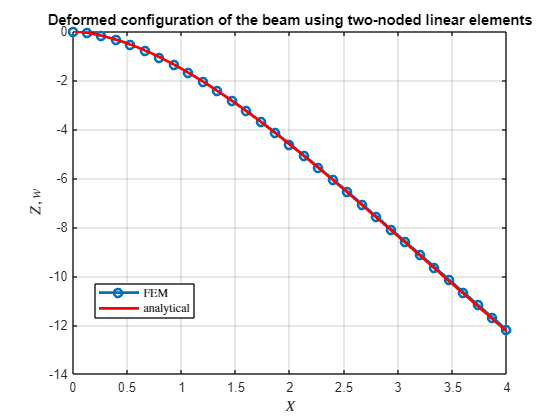

plot(mshL1.nodes, u_L1(1:2:end, 1), '-o', LineWidth=2);
hold on;
fplot(wEx, [0, XL], 'r-', LineWidth=2);
hold off;
grid on;
xlabel("$X$", Interpreter="latex")
ylabel("$Z,w$", Interpreter="latex")
legend("FEM", "analytical",Interpreter="latex",Location="best")
title("Deformed configuration of the beam using two-noded linear elements")

#### Visualization of the solution in terms of the rotational field

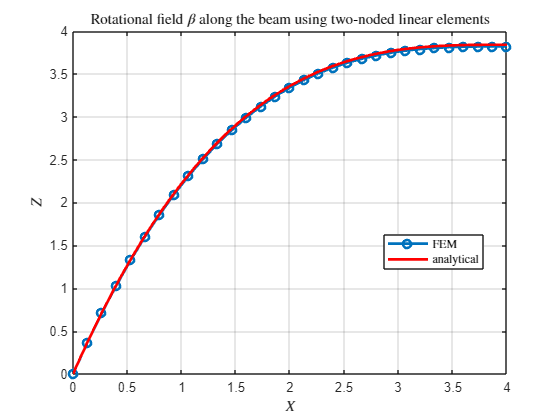

plot(mshL1.nodes, u_L1(2:2:end, 1), '-o', LineWidth=2);
hold on;
fplot(betaEx, [0, XL], 'r-', LineWidth=2);
hold off;
grid on;
xlabel("$X$", Interpreter="latex")
ylabel("$Z$", Interpreter="latex")
legend("FEM", "analytical",Interpreter="latex",Location="best")
title("Rotational field $\beta$ along the beam using " + ...
    "two-noded linear elements", Interpreter="latex")

### Three-noded quadratic elements

#### Solution of the linear equation system

u_L2 = zeros(numDOFsL2, 1);
u_L2(freeDOFsL2) = KL2(freeDOFsL2, freeDOFsL2)\FL2(freeDOFsL2);

#### Visualization of the solution in terms of the vertical displacement field

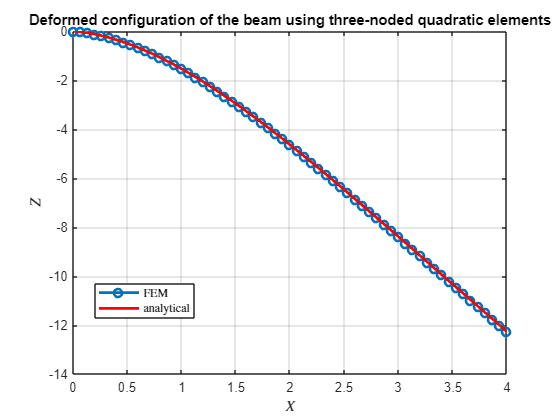

[nodes_L2, idx] = sort(mshL2.nodes);
u_L2_sorted_w = u_L2(1:2:end, 1);
u_L2_sorted_w = u_L2_sorted_w(idx);
plot(nodes_L2, u_L2_sorted_w, '-o', LineWidth=2);
hold on;
fplot(wEx, [0, XL], 'r-', LineWidth=2);
hold off;
grid on;
xlabel("$X$", Interpreter="latex")
ylabel("$Z$", Interpreter="latex")
legend("FEM", "analytical",Interpreter="latex",Location="best")
title("Deformed configuration of the beam using " + ...
    "three-noded quadratic elements")

#### Visualization of the solution in terms of the rotational field

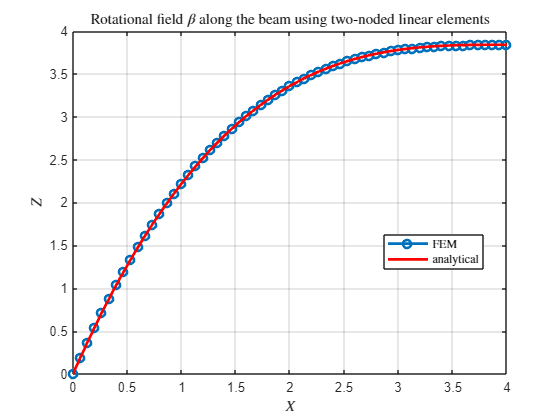

u_L2_sorted_beta = u_L2(2:2:end, 1);
u_L2_sorted_beta = u_L2_sorted_beta(idx);
plot(nodes_L2, u_L2_sorted_beta, '-o', LineWidth=2);
hold on;
fplot(betaEx, [0, XL], 'r-', LineWidth=2);
hold off;
grid on;
xlabel("$X$", Interpreter="latex")
ylabel("$Z$", Interpreter="latex")
legend("FEM", "analytical",Interpreter="latex",Location="best")
title("Rotational field $\beta$ along the beam using " + ...
    "two-noded linear elements", Interpreter="latex")

  **Try**

Change the thickness in this code section by means of the provided numeric slider without modifying the number of Finite Elements and rerun the script.

 **Reflect**

How do the solutions from both discretizations, two-noded linear and three-noded quadratic, change with respect to the analytical solution?

## References

[[1] Hughes, Thomas JR. *The finite element method: linear static and dynamic finite element analysis*. Courier Corporation, 2012.](https://doi.org/10.1111/j.1467-8667.1989.tb00025.x)

[](https://doi.org/10.1007/978-3-030-76035-9)[[2] Öchsner, Andreas. *Classical beam theories of structural mechanics*. Cham: Springer, 2021.](https://doi.org/10.1007/978-3-030-76035-9)

## **Helper functions**

### **Element Stiffness Matrix and body force vector**

function [Ke, Fe] = computeElementStiffnessMatrixandForceVectorTimoshenkoBeam ...
    (N, nodesEl, propStr)

**Function description**

Computation of the element stiffness matrix for an element based on the 1D Timoshenko-beam theory with two degrees of freedom per node $\left(w,\beta \right)$, one of the vertical deflection and another one for the shear rotation:


$$\begin{array}{l}
K_{\textrm{ij}}^w =\int_0^l \alpha \textrm{GA}\left(\frac{dN_i^w }{\textrm{dX}}+N_i^{\beta } \right)\left(\frac{dN_j^w }{\textrm{dX}}+N_j^{\beta } \right)\textrm{dx}\;,\\
K_{\textrm{ij}}^{\beta } =\int_0^l \textrm{EI}\left(\frac{dN_i^{\beta } }{\textrm{dx}}\right)\frac{dN_j^{\beta } }{\textrm{dx}}\;\;\textrm{dx}\;\ldotp 
\end{array}$$


**             Input :**

                    `N` : Vector containing the symbolic expression for the basis functions

        `nodesEl` : Nodal coordinates of the finite element arranged in a column-vector

        `propStr` : Structure containing the following fields,

                              `.A` : Cross sectional area of the beam

                              `.q` : Distributed load on the beam

                              `.m` : Distributed moment on the beam

                              `.E` : Young's modulus

                            `.nu` : Poisson's ratio

                              `.I` : Moment of inertia

                              `.G` : Shear modulus

                      `.alpha` : Shear correction factor

**          Output :**

`         Ke` : Element stiffness matrix of a Timoshenko beam

                  `Fe` : Element force vector of the Timoshenko beam

**Function implementation**

Set-up the geometric map $x(\xi) = \sum_{i=1}^n N_i(\xi) x_i$:

syms xi
numNodesEl = numel(N(xi));
xel = sym('xel', [numNodesEl 1]);
x = N*xel;

Get the polynomial order of the element

pEl = numNodesEl - 1;

Get the number of DOFs per element

numDOFsEl = 2*numNodesEl;

Set-up the Jacobian $J(\xi) = \frac{\text{d} x(\xi)}{\text{d} \xi} = \sum_{i = 1}^n \frac{\text{d} N_i(\xi)}{\text{d} \xi}x_i$:

J = jacobian(x, xi);

Transform the derivatives of the basis functions from the parametric to the physical space


$$\frac{\text{d} N_i (\xi)}{\text{d} x} = \frac{\text{d} N_i (\xi)}{\text{d} \xi} \frac{\text{d} \xi}{\text{d} x} = \frac{\text{d} N_i (\xi)}{\text{d} \xi} J^{-1}$$
  

syms dN(xi)
dN(xi) = J\diff(N, xi);

Computation of the material matrix

syms alpha_scf G A E I
C = [alpha_scf*G*A 0
     0             E*I];

Symbolic formulation of the basis function matrix

Nmtx = sym(zeros(2, numDOFsEl));
for ii = 1:numNodesEl
    filtermtx = zeros(numNodesEl, 1);
    filtermtx(ii) = 1;
    Nmtx(1, 2*ii - 1) = N*filtermtx;
    Nmtx(2, 2*ii) = N*filtermtx;
end

Symbolic formulation of the B-Operator matrix

Bmtx = sym(zeros(2, numDOFsEl));
for ii = 1:numNodesEl
    filtermtx = zeros(numNodesEl, 1);
    filtermtx(ii) = 1;
    Bmtx(1, 2*ii - 1) = dN*filtermtx;
    Bmtx(1, 2*ii) = N*filtermtx;
    Bmtx(2, 2*ii) = dN*filtermtx;
end

Set up element stiffness matrix and load vector integrands

syms qBar mBar Ke_integrand(xi) Fe_integrand(xi)
Ke_integrand(xi) = transpose(Bmtx)*C*Bmtx;
Fe_integrand(xi) = transpose(Nmtx)*[qBar; mBar];

Choose method for computing the element stiffness matrix

integrationMethod = 2;

Compute the symbolic expression of the element stiffness matrix and load vector based on the selected method

switch integrationMethod

*1.) Method 1: Perform the variable substitution *$\xi =\xi \left(X\right)$ which is the inverse of map $X=X\left(\xi \right)$:

    case 0


$$B\left(\xi \right)=B\left(\xi \left(X\right)\right)=\bar{B} \left(X\right),$$



$$\int_{X_1 }^{X_2 } B^T \left(\xi \right)\textrm{CB}\left(\xi \right)\;\textrm{dx}=\int_{X_1 }^{X_2 } {\bar{B} }^T \left(x\right)C\bar{B} \left(x\right)\;\textrm{dx}$$



$$\int_{X_1 }^{X_2 } N^T \left(\xi \right)p\left(\xi \right)\;\textrm{dx}=\int_{X_1 }^{X_2 } {\bar{N} }^T \left(x\right)\bar{p} \left(x\right)\;\textrm{dx}$$


        syms X
        Xxi = solve(X == x(xi), xi);
        Ke_integrand_bar = subs(Ke_integrand, xi, Xxi);
        Fe_integrand_bar = subs(Fe_integrand, xi, Xxi);
        Ke_int = int(Ke_integrand_bar, X, nodesEl(1), nodesEl(2));
        Fe_int = int(Fe_integrand_bar, X, nodesEl(1), nodesEl(2));

*2.) Method 2: Transform the element stiffness matrix in the element's parent space [-1 , 1]:*

    case 1


$$\int_{X_1 }^{X_2 } B^T \left(\xi \right)\textrm{CB}\left(\xi \right)\;\textrm{dX}=\int_{-1}^{+1} B^T \left(\xi \right)\textrm{CB}\left(\xi \right)\;\det \left(J\left(\xi \right)\right)\;d\xi$$



$$\int_{X_1 }^{X_2 } N\left(\xi \right)p\left(\xi \right)\;\textrm{dX}=\int_{-1}^{+1} N\left(\xi \right)p\left(\xi \right)\;\det \left(J\left(\xi \right)\right)\;d\xi$$


Symbolic computation of the element stiffness matrix

        Ke_int = int(Ke_integrand*det(J), xi, -1, 1);
        Fe_int = int(Fe_integrand*det(J), xi, -1, 1);

*3.) Method 3: Transform the element stiffness matrix in the element's parent space [-1 , 1] and perform Gaussian integration*

    case 2


$$\int_{X_1 }^{X_2 } B^T \left(\xi \right)\textrm{CB}\left(\xi \right)\;\textrm{dx}=\int_{-1}^{+1} B^T \left(\xi \right)\textrm{CB}\left(\xi \right)\;\det \left(J\left(\xi \right)\right)\;d\xi =\sum_{i=1}^2 B^T \left(\xi_i \right)\textrm{CB}\left(\xi_i \right)\;\det \left(J\left(\xi_i \right)\right)w_i$$



$$\int_{X_1 }^{X_2 } N\left(\xi \right)p\left(\xi \right)\;\textrm{dx}=\int_{-1}^{+1} N\left(\xi \right)p\left(\xi \right)\;\det \left(J\left(\xi \right)\right)\;d\xi =\sum_{i=1}^2 N\left(\xi_i \right)p\left(\xi_i \right)\;\det \left(J\left(\xi_i \right)\right)w_i$$


Symbolic computation of the element stiffness matrix

        numGP = pEl + 1;
        [xiGP, GW_xi] = getGaussPointsAndWeightsOverUnitDomain(numGP);
        Ke_int = sym(zeros(numDOFsEl));
        Fe_int = sym(zeros(numDOFsEl, 1));
        for ii = 1:height(GW_xi)
            Ke_int = Ke_int + Ke_integrand(xiGP(ii))*det(J(xiGP(ii)))*GW_xi(ii);
            Fe_int = Fe_int + Fe_integrand(xiGP(ii))*det(J(xiGP(ii)))*GW_xi(ii);
        end

*4.) Method 4: Transform the element stiffness matrix in the element's parent space [-1 , 1] and perform reduced integration*

    case 3


$$\int_{X_1 }^{X_2 } B^T \left(\xi \right)\textrm{CB}\left(\xi \right)\;\textrm{dx}=\int_{-1}^{+1} B^T \left(\xi \right)\textrm{CB}\left(\xi \right)\;\det \left(J\left(\xi \right)\right)\;d\xi =\sum_{i=1}^1 B_{\textrm{shear}}^T \left(\xi_i \right)C_{\textrm{shear}} B_{\textrm{shear}} \left(\xi_i \right)\;\det \left(J\left(\xi_i \right)\right)w_i +\sum_{i=1}^2 B_{\textrm{bending}}^T \left(\xi_i \right)C_{\textrm{bending}} B_{\textrm{bending}} \left(\xi_i \right)\;\det \left(J\left(\xi_i \right)\right)w_i$$



$$\int_{X_1 }^{X_2 } N\left(\xi \right)p\left(\xi \right)\;\textrm{dx}=\int_{-1}^{+1} N\left(\xi \right)p\left(\xi \right)\;\det \left(J\left(\xi \right)\right)\;d\xi =\sum_{i=1}^n N\left(\xi_i \right)p\left(\xi_i \right)\;\det \left(J\left(\xi_i \right)\right)w_i$$


Symbolic computation of the element stiffness matrix using Gaussian integration:

        syms Ke_shear_integrand(xi) Ke_bending_integrand(xi) Fe_integrand(xi)
        Ke_shear_integrand(xi) = [[1 0]*Bmtx
                                  sym(zeros(1, numDOFsEl))]'*C*[[1 0]*Bmtx
                                  sym(zeros(1, numDOFsEl))];
        Ke_bending_integrand(xi) = [sym(zeros(1, numDOFsEl))
                                    [0 1]*Bmtx]'*C*[sym(zeros(1, numDOFsEl))
                                    [0 1]*Bmtx];
        Fe_integrand(xi) = transpose(Nmtx)*[qBar; mBar];

Compute the shear part of the stiffness matrix using reduced integration (number of required Gauss points for integration without rigid body modes minus one):

        numGP = pEl;
        [xiGP, GW_xi] = getGaussPointsAndWeightsOverUnitDomain(numGP);
        Ke_shear_int = sym(zeros(numDOFsEl));
        for ii = 1:height(GW_xi)
            Ke_shear_int = Ke_shear_int + ...
                Ke_shear_integrand(xiGP(ii))*det(J(xiGP(ii)))*GW_xi(ii);
        end

Compute the bending part of the stiffness matrix using full integration (number of required Gauss points for integration without rigid body modes):

        numGP = pEl + 1;
        [xiGP, GW_xi] = getGaussPointsAndWeightsOverUnitDomain(numGP);
        Ke_bending_int = sym(zeros(numDOFsEl));
        Fe_int = sym(zeros(numDOFsEl, 1));
        for ii = 1:height(GW_xi)
            Ke_bending_int = Ke_bending_int + ...
                Ke_bending_integrand(xiGP(ii))*det(J(xiGP(ii)))*GW_xi(ii);
            Fe_int = Fe_int + ...
                Fe_integrand(xiGP(ii))*det(J(xiGP(ii)))*GW_xi(ii);
        end

Add the shear and the bending parts of the stiffness matrix:

        Ke_int = Ke_shear_int + Ke_bending_int;

Assert an error in case neither of cases 0, 1, 2 or 3 is chosen:

    otherwise
        error("Variable 'method' should take the values 0, 1, 2 or 3 but it has instead the value %d\n", integrationMethod);
end

Numerical evaluation of the element stiffness matrix and load vector

Ke = subs(Ke_int, [alpha_scf, G, E, A, I, transpose(xel)], ...
    [propStr.alpha, propStr.G, propStr.E, propStr.A, ...
    propStr.I, transpose(nodesEl)]);
Fe = subs(Fe_int, [qBar, mBar, transpose(xel)], ...
    [propStr.qBar, propStr.mBar, transpose(nodesEl)]);

Computation of the analytical formula for the stiffness matrix

isDebug = false;
if isDebug
    Ke_analytical = [propStr.alpha*propStr.G*propStr.A/(x2 - x1)  -propStr.alpha*propStr.G*propStr.A/2                                           -propStr.alpha*propStr.G*propStr.A/(x2 - x1) -propStr.alpha*propStr.G*propStr.A/2
                     -propStr.alpha*propStr.G*propStr.A/2         -propStr.alpha*propStr.G*propStr.A*(x2 - x1)/3 + propStr.E*propStr.I/(x2 - x1) propStr.alpha*propStr.G*propStr.A/2          propStr.alpha*propStr.G*propStr.A*(x2 - x1)/6 - propStr.E*propStr.I/(x2 - x1)
                     -propStr.alpha*propStr.G*propStr.A/(x2 - x1) propStr.alpha*propStr.G*propStr.A/2                                            propStr.alpha*propStr.G*propStr.A/(x2 - x1)  propStr.alpha*propStr.G*propStr.A/2
                     -propStr.alpha*propStr.G*propStr.A/2         propStr.alpha*propStr.G*propStr.A*(x2 - x1)/6 - propStr.E*propStr.I/(x2 - x1) propStr.alpha*propStr.G*propStr.A/2           propStr.alpha*propStr.G*propStr.A*(x2 - x1)/3 + propStr.E*propStr.I/(x2 - x1)];
    err = norm(Ke - Ke_analytical, "fro");
end

end